clc;clear all;

t = readtable("Thrust_vs_Theta.xlsx");
theta = (t.Theta(1:5)).';
CTvsp = (t.CTvsp(29:33)).';
CTbmt = (t.CTbmt(29:33)).';

dTheta_dCTvsp = gradient(CTvsp,CTbmt);
dTheta_dCTbmt = gradient(theta);

x = dTheta_dCTvsp/dTheta_dCTbmt;
fprintf("ratio = %.5f\n",x);

ratio = 0.19030


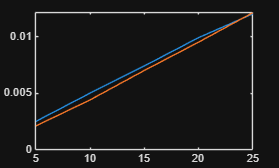

plot(theta,CTvsp);
hold on;
plot(theta,CTbmt);
hold off;